## Using SP500 to Predict TVIX

## 1.Data Collection and Processing

I collected 5y data of SP500 and TVIX from Yahoo Finance and calculated log-return. 

clc;close;clear;

startdate='1-April-2015';
enddate='1-April-2020';
interval = '1d';
symbol1 ='^GSPC';
data1 = getMarketDataViaYahoo(symbol1,startdate,enddate,interval);
symbol2 ='TVIX';
data2 = getMarketDataViaYahoo(symbol2,startdate,enddate,interval);

X=log(data1{2:end,6}./data1{1:end-1,6});
y=log(data2{2:end,6}./data2{1:end-1,6});

## 2. Exploratory Data Analysis

I drew scatterplot of X and y.

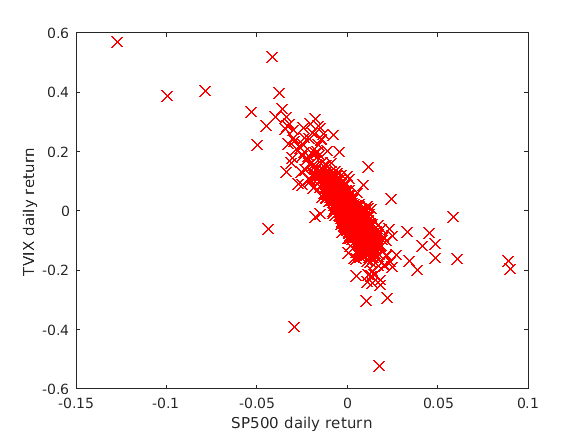

% m = Number of examples for training, validation and test
m = size(X, 1);

% Scatter-plot data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('SP500 daily return');
ylabel('TVIX daily return');

## 3. Data Transformation

### 3.1 Feature Engineering

The problem with the simple linear model (i.e., a linear regression of y only on X) was that it was too simple for the data and would likely result in underfitting (high bias). I addressed this problem by adding more features in the form of polynomial terms in feature vector X. 

% p = largest exponent in polynomial terms
p=10;
for i=1:p
X(:,i)=X(:,1).^i;        
end

### 3.2 Feature Scaling

I standardized the features to make regularization more convenient.

X=(X-mean(X))./std(X);

### 3.3 Adding the Intercept

The last step of data transformation was adding the intercept.

X=[ones(m,1) X];

### 3.4 Sampling

I randomly drew 60% data as training set, 20% as validation set, 20% as test set.

% 6-2-2 split train, validation and test data

randrow=randperm(size(X, 1));
m_training=round(size(X,1)*0.6);
m_validation=round(size(X,1)*0.2);
m_test=m-m_training-m_validation;
X_training=X(randrow(1:m_training),:);
y_training=y(randrow(1:m_training),:);
X_validation=X(randrow(m_training+1:m_training+m_validation),:);
y_validation=y(randrow(m_training+1:m_training+m_validation),:);
X_test=X(randrow(m_training+m_validation+1 : end),:);
y_test=y(randrow(m_training+m_validation+1 : end),:);

## 4.Model Training and Fine-tuning

### 4.1 Regularized Linear Regression Cost Function and Gradient

Regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

I completed code of the function to calculate the regularized linear regression cost function in the file `linearRegCostFunction.m.` 

function [J, grad] = linearRegCostFunction(X, y, theta, lambda)

...

end

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\textrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\textrm{for}\;\;j=0
\end{array}$$


In `linearRegCostFunction.m`, I also completed code of the function to calculate the regularized linear regression gradient.

Plus, given a dataset (X, y) and a regularization parameter lambda, I wrote a function `trainLinearReg.m `to return optimized $\theta$.

function [theta] = trainLinearReg(X, y, lambda)

...

end

### 4.2 Learning Curves

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. Thus, I plotted training and cross validation errors on learning curves as a function of training subset size $m$ to diagnose bias-variance problems.

Training cost function with training subset size $m\;\left(m\le m_{\textrm{train}} \right)$ is defined as


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right),m\le m_{\textrm{train}}$$


Even if training may have a positive regularization parameter $\lambda$, the training error, different from the training cost which has regularization terms, is defined as


$$J_{\textrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack ,m\le m_{\textrm{train}}$$


Regardless of regularization parameter $\lambda$ and training subset size $m\;\left(m\le m_{\textrm{train}} \right)$, the cross validation error is always defined as


$$J_{\textrm{cv}} \left(\theta \right)=\frac{1}{2m_{\textrm{cv}} }\left\lbrack \sum_{i=1}^{m_{\textrm{cv}} } {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


I filled in `learningCurve.m` so that it would return a vector of errors for the training set and cross validation set. 

function [error_train, error_val] =   learningCurve(X_training, y_training, X_validation, y_validation, lambda)

...

end

For convenience, I also set training subset size $m\le$100 in the function.

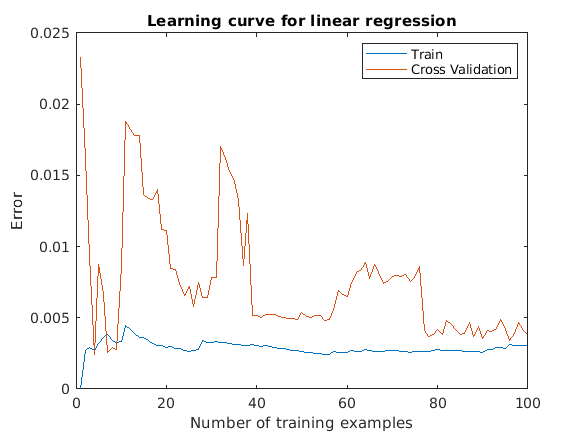

lambda = 0.1;
[error_train, error_val] = ...
 learningCurve(X_training, y_test, X_validation, y_validation, lambda);
figure(1);
plot(1:length(error_train), error_train, ...
    1:length(error_train), error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')

### 4.3 Selecting Lambda Using Validation Curves

The value of $\lambda$ can significantly affect the results of regularized regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data. I implemented an automated method to select the parameter. Concretely, I used a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. I completed the code in `validationCurve.m` to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10, 30, 100}.

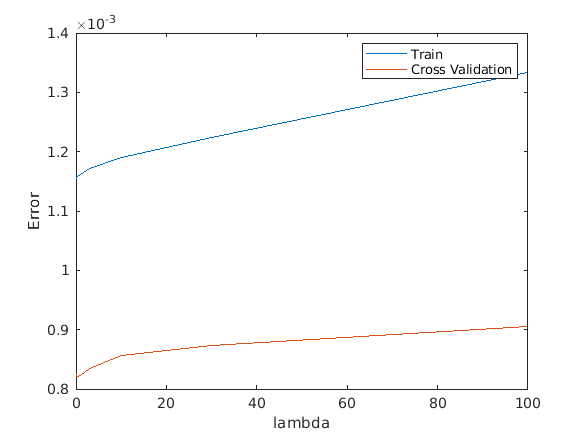

[lambda_vec, error_train, error_val] = ...
 validationCurve(X_training, y_training, X_validation, y_validation);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');

for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

lambda		Train Error	Validation Error


0.000000	0.001157	0.000821
0.001000	0.001156	0.000824
0.003000	0.001156	0.000822
0.010000	0.001155	0.000827
0.030000	0.001156	0.000822
0.100000	0.001157	0.000821
0.300000	0.001158	0.000820
1.000000	0.001162	0.000822
3.000000	0.001172	0.000834
10.000000	0.001191	0.000857
30.000000	0.001225	0.000873
100.000000	0.001333	0.000906


## 5. Test Results

Based on validation curves, I picked best $\lambda$ for regression model to go through final test. 

[~,min_index]=min(error_val);
lambda_best=lambda_vec(min_index);
[error_test,~] =linearRegCostFunction(X_test, y_test, ...
    trainLinearReg(X_training, y_training,lambda_best), 0);
fprintf("Test Error is %.8f (lambda=%.8f).", error_test,lambda_best);

Test Error is 0.00140324 (lambda=0.30000000).